clc
% clear
close all
load("sim_podre.mat")

### VEHICLE

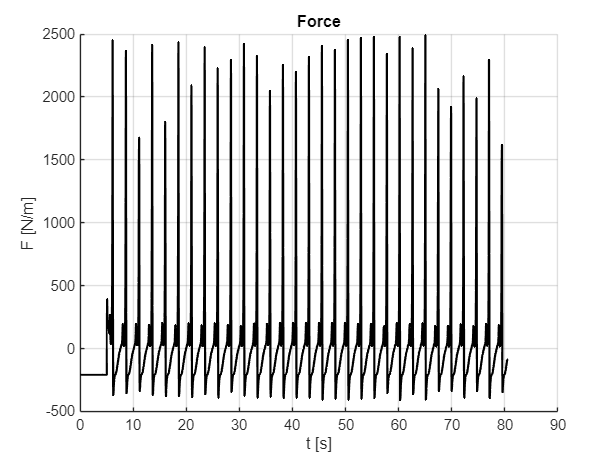

plotVariable(out.main_clock, out.F_total(:, 3), "t [s]", "F [N/m]", "Force")

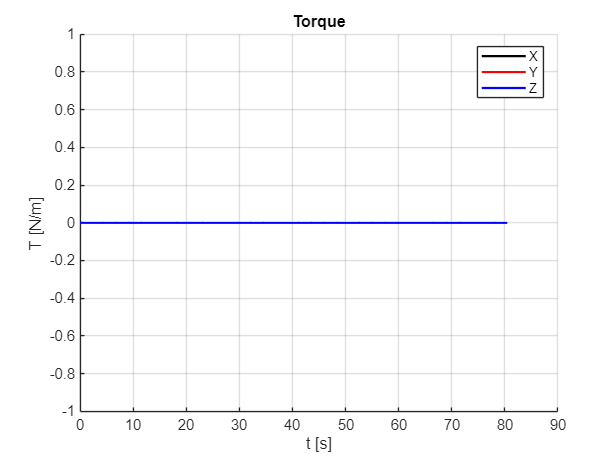

plotVariable(out.main_clock, out.T_total, "t [s]", "T [N/m]", "Torque")

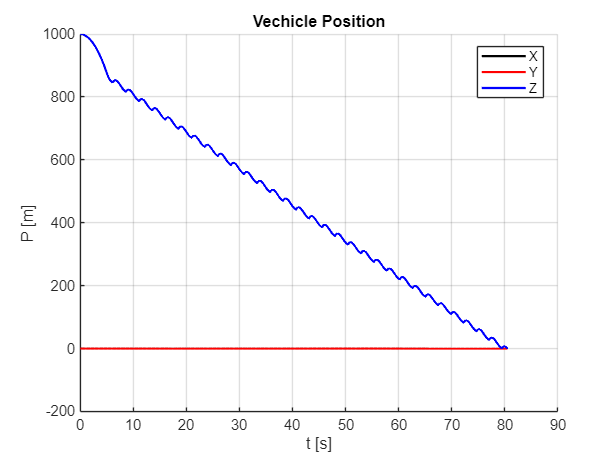

plotVariable(out.main_clock, out.vehicle_position, "t [s]", "P [m]", "Vechicle Position")

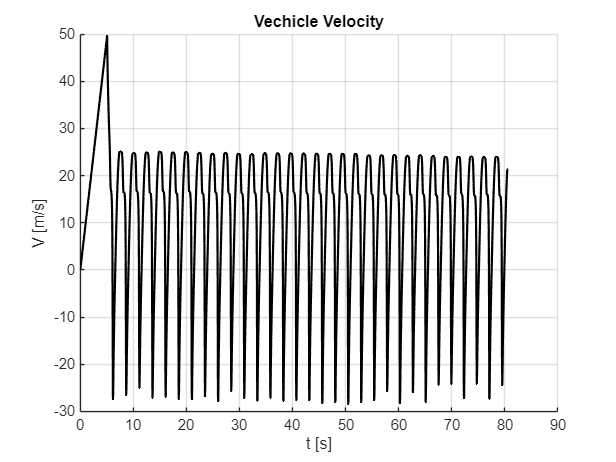

plotVariable(out.main_clock, -out.vehicle_velocity(: , 3), "t [s]", "V [m/s]", "Vechicle Velocity")

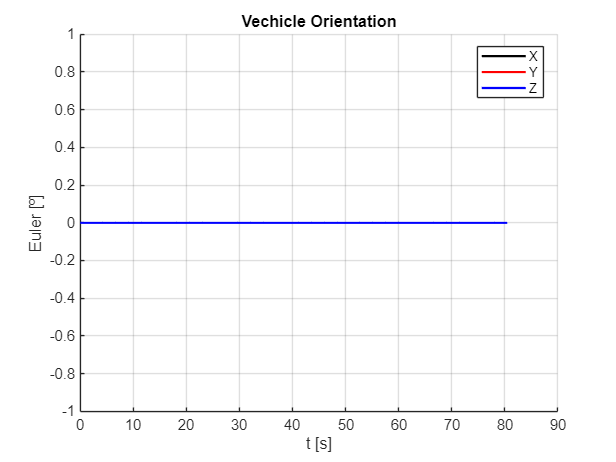

plotVariable(out.main_clock, out.vehicle_orientation, "t [s]", "Euler [º]", "Vechicle Orientation")

### ROTOR

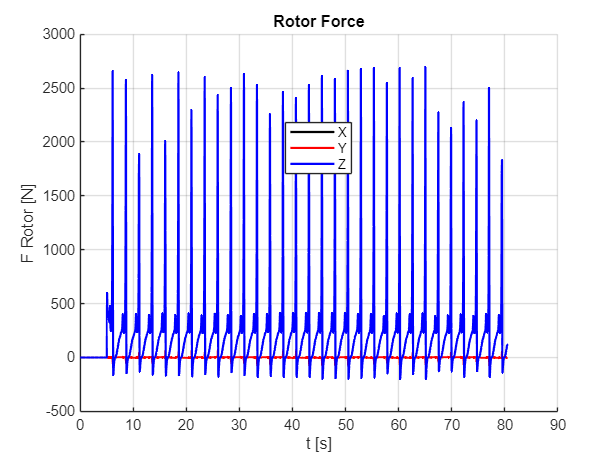

plotVariable(out.main_clock, out.F_rotor, "t [s]", "F Rotor [N]", "Rotor Force")

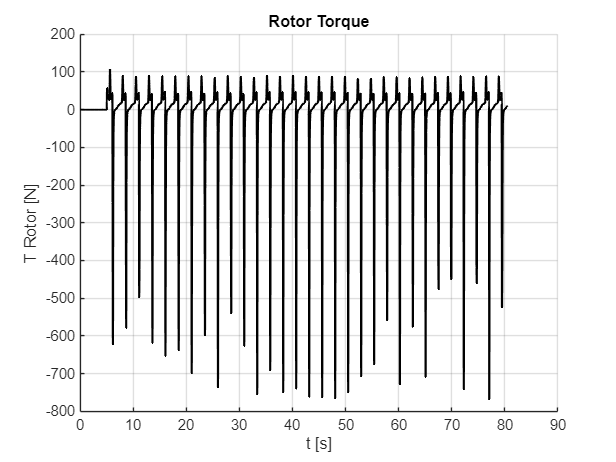

plotVariable(out.main_clock, out.T_rotor, "t [s]", "T Rotor [N]", "Rotor Torque")

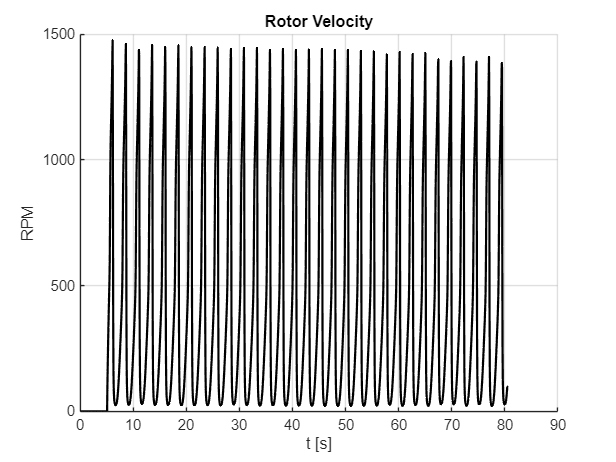

plotVariable(out.main_clock, out.rotor_velocity * 60 / (2*pi), "t [s]", "RPM", "Rotor Velocity")

plotVariable(out.main_clock, -out.rotor_induced_velocity, "t [s]", "V_i [m/s]", "Induced Velocity")

Unable to resolve the name 'out.main_clock'.

xlim([30 40])

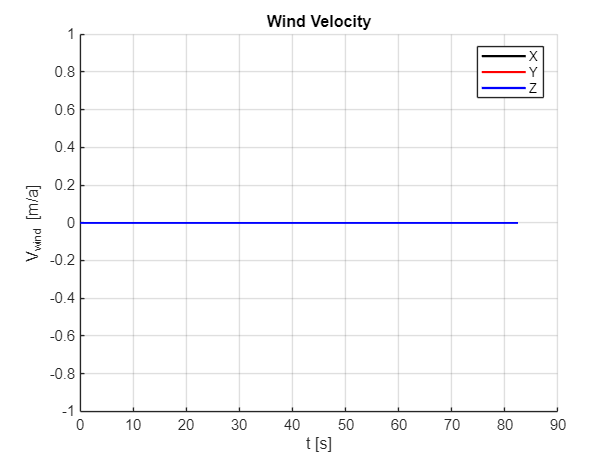


plotVariable(out.main_clock, out.wind_velocity, "t [s]", "V_{wind} [m/a]", "Wind Velocity")

### BLADE DISTRIBUTION ANALYSIS

t = 100;
azimute = 90;
[~, i] = min(abs(out.rotor_data.time - t));
data_rotor = out.rotor_data.data(i);
[~, i] = min(abs(data_rotor.azimutal_position - azimute));
data_blade = data_rotor.blade_distribution_data(i);
xx = (0:50) * (1/70) + 0;
azimutes = data_rotor.azimutal_position;

#### Velocity

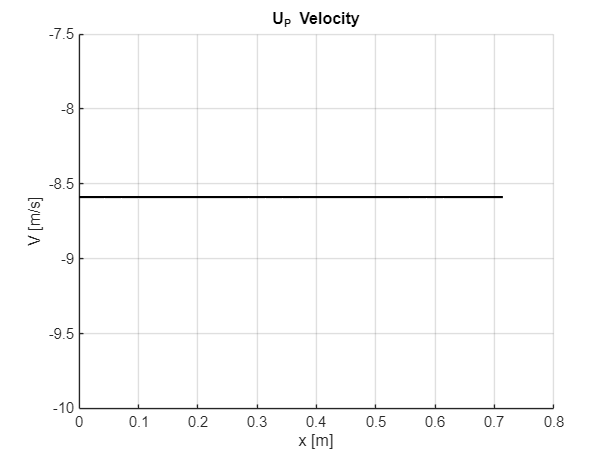

plotVariable(xx, data_blade.U_P, "x [m]", "V [m/s]", "U_P Velocity")

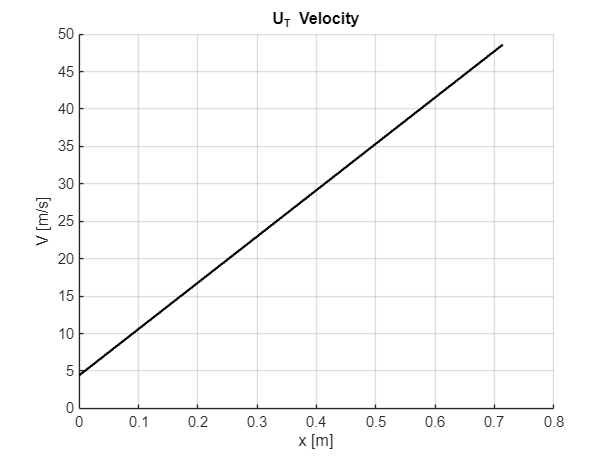

plotVariable(xx, data_blade.U_T, "x [m]", "V [m/s]", "U_T Velocity")

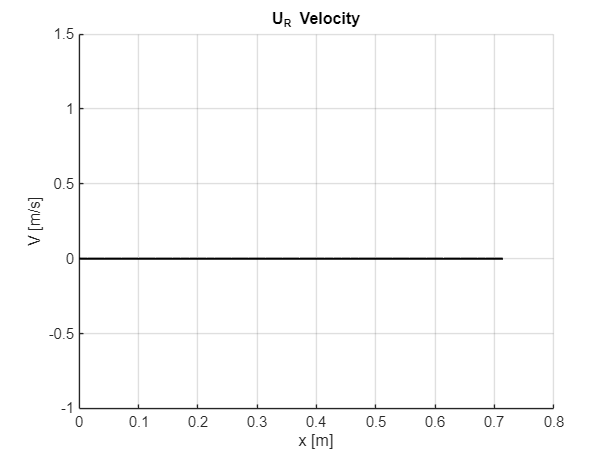

plotVariable(xx, data_blade.U_R, "x [m]", "V [m/s]", "U_R Velocity")

#### Angles

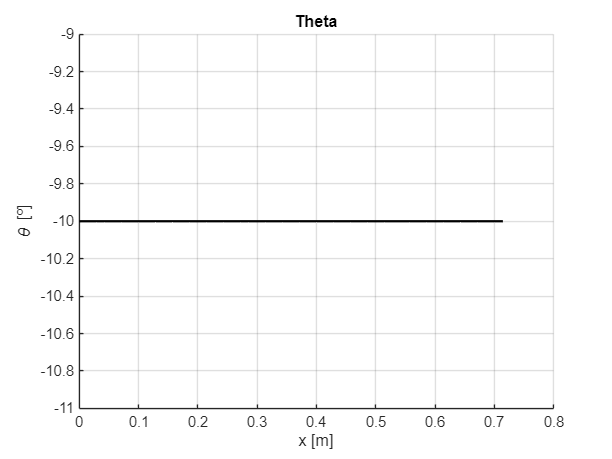

plotVariable(xx, data_blade.theta, "x [m]", "\theta [º]", "Theta")

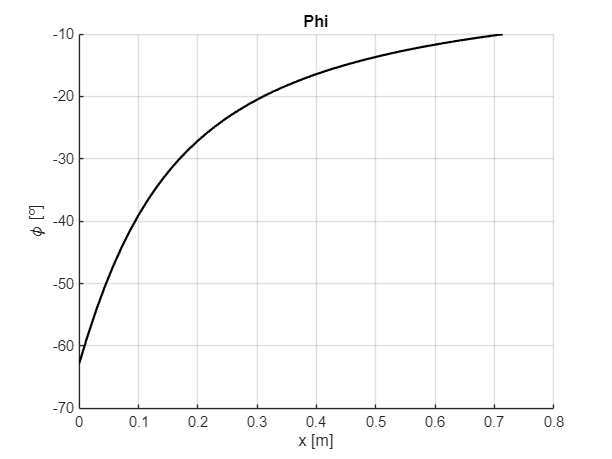

plotVariable(xx, data_blade.phi, "x [m]", "\phi [º]", "Phi")

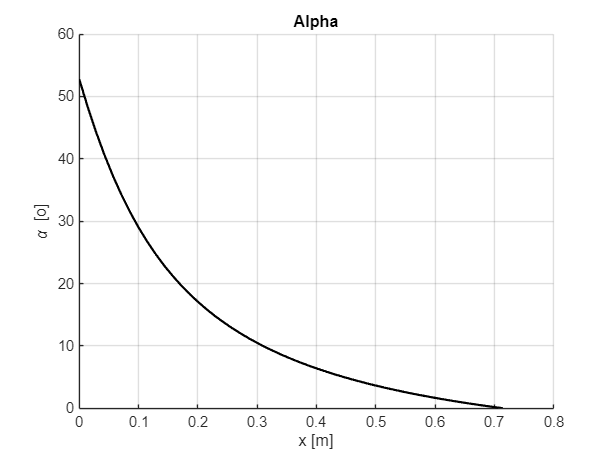

plotVariable(xx, data_blade.alpha, "x [m]", "\alpha [o]", "Alpha")

#### Reynolds Number

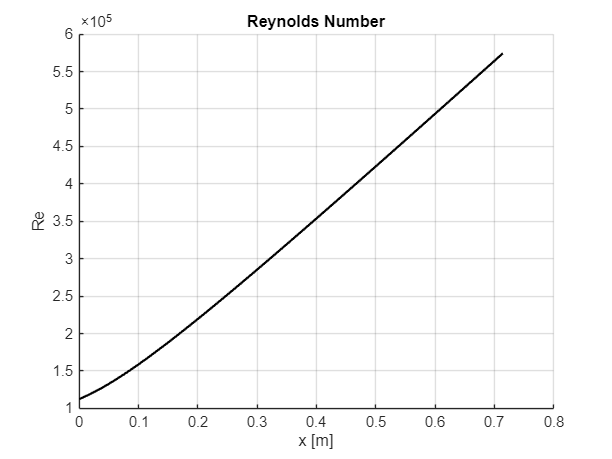

plotVariable(xx, data_blade.Re, "x [m]", "Re", "Reynolds Number")

#### Aerodynamic Coefficients

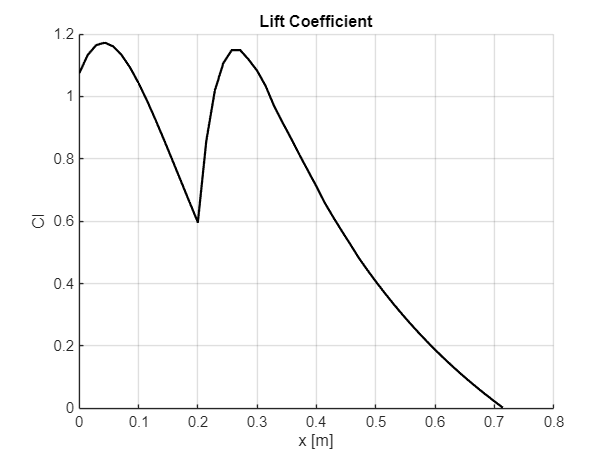

plotVariable(xx, data_blade.Cl, "x [m]", "Cl", "Lift Coefficient")

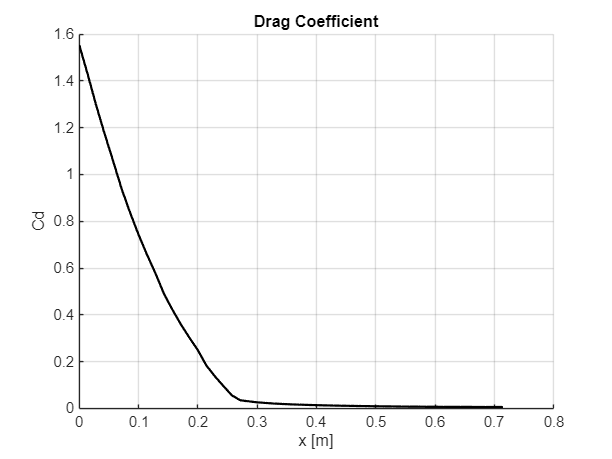

plotVariable(xx, data_blade.Cd, "x [m]", "Cd", "Drag Coefficient")

#### Forces in Aerodynamic Frame

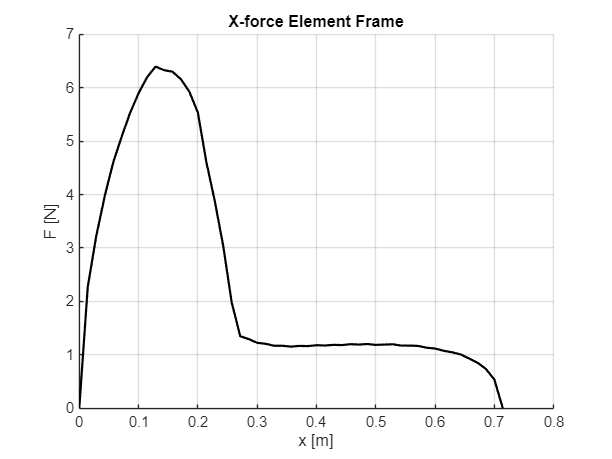

plotVariable(xx, data_blade.dF_a_x, "x [m]", "F [N]", "X-force Element Frame")

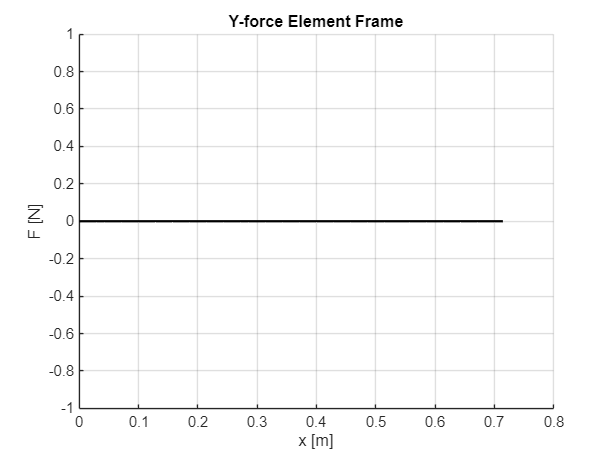

plotVariable(xx, data_blade.dF_a_y, "x [m]", "F [N]", "Y-force Element Frame")

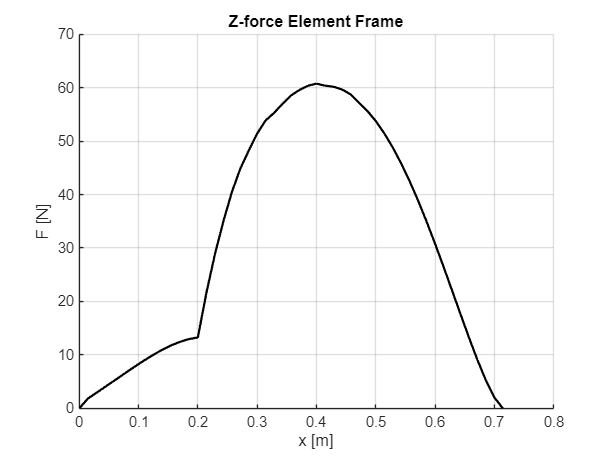

plotVariable(xx, data_blade.dF_a_z, "x [m]", "F [N]", "Z-force Element Frame")

#### Forces in Element Frame

Aqui o sinal (-) significa que a contribuição da força aerodinâmica gera uma força que cria rotação

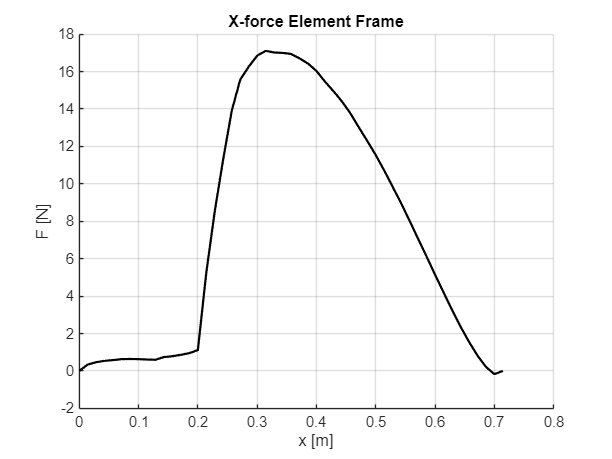

plotVariable(xx, -data_blade.dF_e_x, "x [m]", "F [N]", "X-force Element Frame")

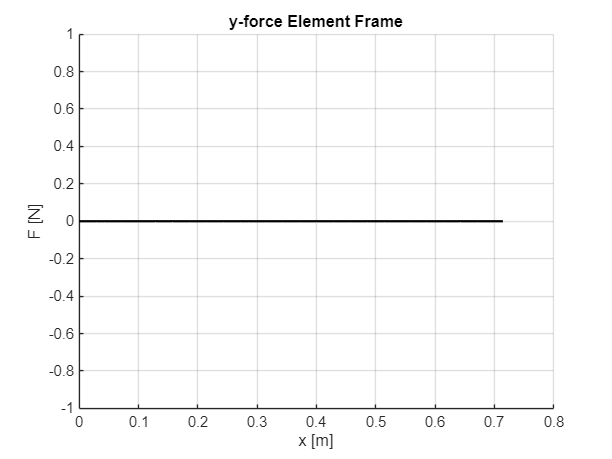

plotVariable(xx, data_blade.dF_e_y, "x [m]", "F [N]", "y-force Element Frame")

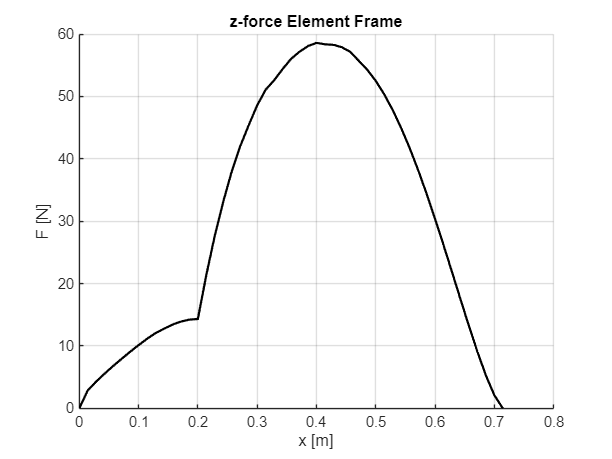

plotVariable(xx, data_blade.dF_e_z, "x [m]", "F [N]", "z-force Element Frame")

#### Prandtl Function

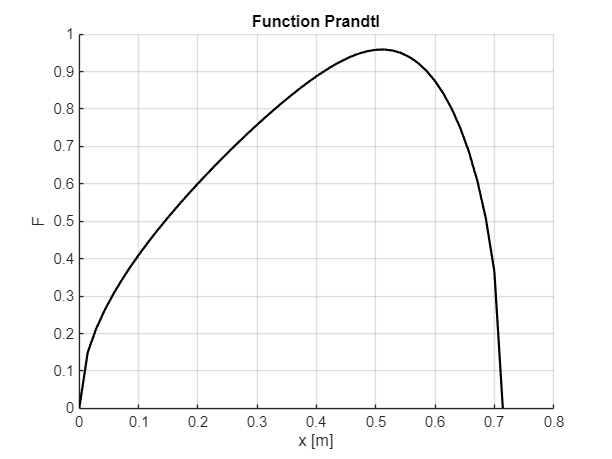

plotVariable(xx, data_blade.f_prandtl, "x [m]", "F", "Function Prandtl")

### ROTOR DISTRIBUTION ANALYSIS

#### Forces

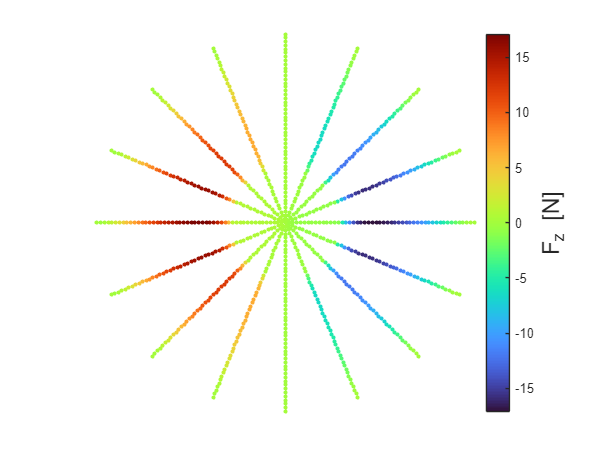

for i=1:length(azimutes)
    values(i, :) = data_rotor.blade_distribution_data(i).dF_i_x;
end
polarPlot(azimutes, xx, values, "", "F_z [N]", "")

for i=1:length(azimutes)
    values(i, :) = data_rotor.blade_distribution_data(i).dF_r_y;
end

Unrecognized method, property, or field 'dF_r_y' for class 'BladeDistribution'.

polarPlot(azimutes, xx, values, "", "F_y [N]", "")
for i=1:length(azimutes)
    values(i, :) = data_rotor.blade_distribution_data(i).dF_r_z;
end
polarPlot(azimutes, xx, values, "", "F_z [N]", "")